clear
cd('C:\Users\sydne\Documents\github\perceive')
%jsonFiles = 'Report_Json_Session_Report_20210604T094200.json';
jsonFiles = 'pt2_0604_rl_survey.json'; 
cd('C:\Users\sydne\Documents\github\perceive')
js = jsondecode(fileread(jsonFiles));

channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
sides = {'LEFT', 'RIGHT'};
startindex = 1; 
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2}))) 
        doubleBattery = false; 
        %json has both left and right data 
        channelsLeft = channels(contains(channels, sides{1}));
        channelsRight = channels(contains(channels, sides{2}));
        highestBetas = cell(2);
    else 
        doubleBattery = true; 
end 

maxValuesRight = [0.113335224633850
0.0679342023802419
0.142024749898451
0.0180491201451143
0.0882357354970350
0.0213244490013605] 

maxValuesRight =     0.1133
    0.0679
    0.1420
    0.0180
    0.0882
    0.0213



maxValuesLeft = [1.88410476218372
1.33600069635447
2.83838064892372
0.451991091705118
1.61090431026796
0.188560649526444] 

maxValuesLeft =     1.8841
    1.3360
    2.8384
    0.4520
    1.6109
    0.1886


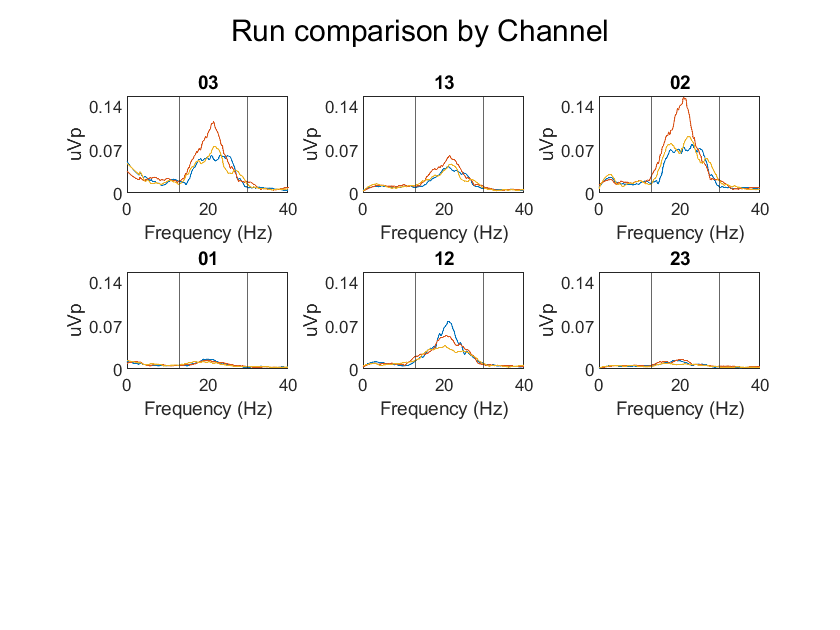


 %graphEachTrials(startindex, js, leng, channelsLeft, max(maxValuesLeft));
 figure; 
 graphEachTrials(startindex, js, leng, channelsRight, max(maxValuesRight));

 % 3 vals 